# **Численные методы в СПб АУ РАН**

## **Задание по практике №2**

Кузьмичев Артём, 4 курс

## **№4 (алгоритмы и программы к разделу 7.3)**

*Суть задания заключается в модификации уже имеющейся программы:*

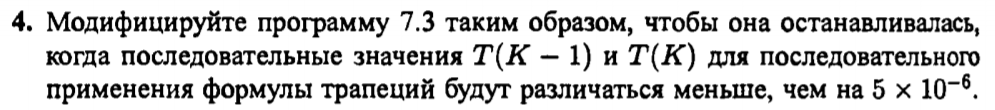

*Изначальный вид программы 7.3*

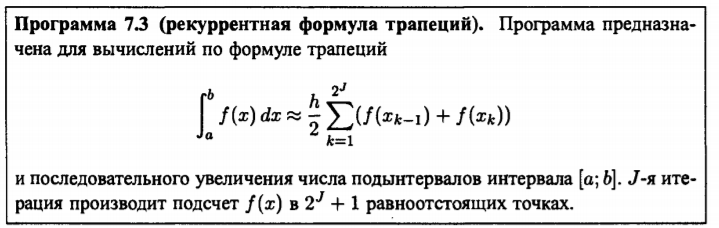

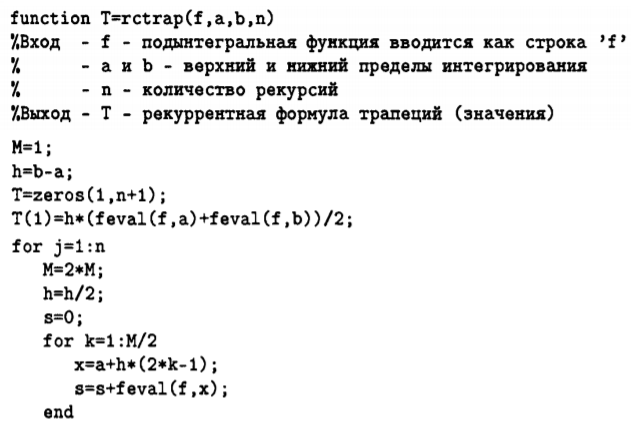

## Реализуем вход алгоритма

f = @(x) x.^2 ;      % подынтегральная функция
a = 0;              % верхний предел интегрирования
b = pi;             % нижний предел интегрирования



n = 100;            % размер массива результатов итерационного алгоритма, преаллоцируемый в памяти перед запуском цикла. 
                    % Данное решение является более быстрым, чем использование динамического массива.
verbosity = 0;      % Указать 1 для вывода информации об итерации во время выполнения алгоритма. verbosity = 0 - silent mode
verbT = 5;          % Период вывода информации, если verbosity = 1
epsilon = 0.001;    % Использование значения из задачи 5 * 10^(-6) возможно, однако программа очень долго будет работать

% epsilon = 5 * 10^(-6);     

## Собственно, алгоритм

Решение заключается в том, что цикл *for* следует заменить на *do while*, с условием выхода $T\left(K+1\right)-T\left(K\right)<\varepsilon$, где $\varepsilon =5\cdot {10}^{-6}$ 

Так как *Matlab* не реализует функционал *do while, *то используется цикл* while* с проверкой условия выхода после отработки каждой итерации

M=1;
h=b-a;

T = zeros(1,n);
T(1)=h*(feval(f,a)+feval(f,b))/2; % начальное приближение формулы трапеций

j = 1; % переменная счётчик

while 1
    M = 2*M;
    h = h/2;
    s = 0;
    for k=1:M/2
        x=a+h*(2*k-1);
        s=s+feval(f,x);
    end
   
    T(j+1)=T(j)/2+h*s;
    
    if abs(T(j+1)-T(j)) < epsilon % проверка условий выхода из цикла
      fprintf("Алгоритм завершил работу на итерации j = %d. Вычисленное значение интеграла S = %d ", j, T(j));
      break;
    end
    
    if verbosity == 1 % вывод информации об итерации
        if mod(j,verbT) == 0
            fprintf("Итерация %d \t ", j)
            fprintf("Значение посчитанной площади на данной итерации: %d \n ", T(j))
            fprintf("Разница между последовательными итерациями: %d \n ", abs(T(j+1)-T(j)));
        end
    end
    
    j = j+1; % инкремент
end

Алгоритм завершил работу на итерации j = 7. Вычисленное значение интеграла S = 1.033669e+01 

Сравним ответ с полученным с помощью использования функции *integral*

integral(f,a,b)

ans = 10.3354